Analisis por municipio (selecciona municipio de 1-10)

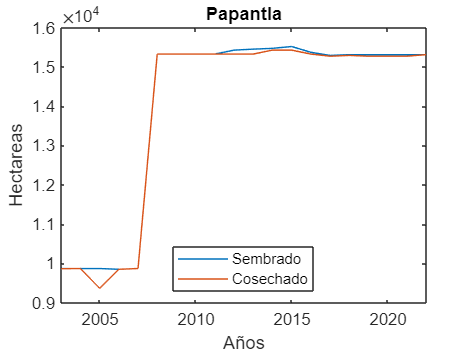

eage_x=2003:2022;
format long;
idx_municipio=4;
plot(eage_x,data_production(idx_municipio).Superficie_sembrada_Ha);
hold on;
plot(eage_x, data_production(idx_municipio).Superficie_cosechada_Ha);
title(data_production(idx_municipio).Municipio);
legend("Sembrado", "Cosechado","Location","south");
xlim([2003 2022])
ylabel("Hectareas")
xlabel("Años")
% ax = gca;
% ax.FontSize=18; 
hold off

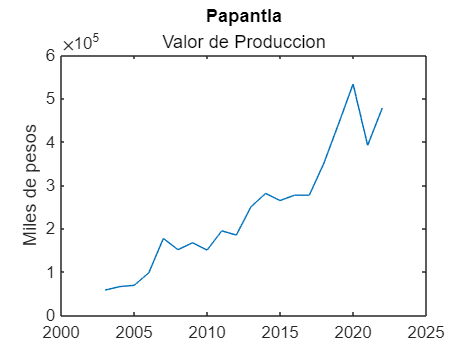


plot(eage_x, data_production(idx_municipio).Valor_Prod)
ylabel("Miles de pesos")
title(data_production(idx_municipio).Municipio,'Valor de Produccion');

## Redes neuronales

% parametros arreglo, area_studio, valor (1 naranja 0 no naranja)
% data_tab_function=f_aplica_formulas(arr_ndvi_sgf,study_area,1)

indxs=find(info_hdf.anio==2022);
% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

datos=arr_ndvi_sgf(:,:,indxs);
% data_tab_function=f_aplica_formulas(datos,study_area,1)
data_tab_test=f_aplica_formulas(datos,study_area,1)

data_tab_test = 27227×9 table
         Mediana             Promedio               Moda                 Rango              Desviacion             Minimos              Maximos                Mad            Valor
    _________________    _________________    _________________    _________________    __________________    _________________    _________________    __________________    _____

    0.576861904761905    0.600469565217391    0.438804761904762    0.381266666666667     0.091807287505087    0.438804761904762    0.820071428571429    0.0727092807633451      1  
    0.606333333333333    0.610131262939959    0.483795238095238    0.235033333333333    0.0690635375862339    0.48379523809

Cargar solo los datos requeridos

data_ndvi=data_tab_function(:,1:8);

## Implementacón de las redes neuronales 

% class_result=model_entrenado.predictFcn(data_ndvi);
% class_result=Model_trained.predictFcn(data_ndvi);
class_result=Trained_model.predictFcn(data_ndvi);

area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);

area_clasificada=arr_ndvi_sgf;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),archivo_kml,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

## Hectareas encontradas

% 1 PX= 250m X 250m=62500 En hectareas 6.25Has
pix_area=sum(area_naranja,"all")

pix_area = 14907

disp("Hectareas Encontradas")

Hectareas Encontradas



fprintf('%.2f\n', pix_area*6.25);

93168.75


## Hectareas por año

data_result=[];
indice=1;
for eage=2003:2022
    indxs=find(info_hdf.anio==eage);
    
    datos=arr_ndvi_sgf(:,:,indxs);
    

% %       data_tab_function=f_aplica_formulas(datos,study_area,1);
%     data_tab_function=f_training_data(datos,study_area,1);


    
% %     data_ndvi=data_tab_function(:,1:8);
%     data_ndvi=data_tab_function(:,1);


% --------------------------------------------------TEMP
    [~,~,pix_tam] =size(datos);
    
    d_res_tmp=[];

    for pxi_i=1:pix_tam
        data_tab_function=f_training_data(datos(:,:,pxi_i),study_area,1);  
        t_pxi=table2array(data_tab_function(:,1));
        d_res_tmp=[d_res_tmp,t_pxi];
    end

% --------------------------------------------------
    class_result=model_entrenado.predictFcn(d_res_tmp);

%     area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);
    
%     pix_area=sum(area_naranja,"all");
    pix_area=sum(class_result)
    
    data_result(indice)=pix_area*6.25;
%     data_result(indice)=pix_area;

   indice=indice+1;
end

pix_area =        21921


pix_area =        18861


pix_area =        17935


pix_area =        20266


pix_area =        24954


pix_area =        18107


pix_area =        21680


pix_area =        17159


pix_area =        20144


pix_area =        16059


pix_area =        18420


pix_area =        21936


pix_area =        21202


pix_area =        14219


pix_area =        17343


pix_area =        20564


pix_area =        21812


pix_area =        14448


pix_area =        20662


pix_area =        19191


## Data result

figure 
hold on;

eage_x=2003:2022;
format long;
idx_municipio=4;
plot(eage_x,data_production(idx_municipio).Superficie_sembrada_Ha);
% 
% plot(eage_x, data_production(idx_municipio).Superficie_cosechada_Ha);
% title(data_production(idx_municipio).Municipio);
plot(eage_x, data_result)
legend("Sembrado", "Red Neuronal","Location","south");


title("Comparacion de resultados",data_production(idx_municipio).Municipio);
xlim([2003 2022])
ylabel("Hectareas")
xlabel("Años")
ax = gca;
ax.FontSize=18; 

err=immse(data_production(idx_municipio).Superficie_sembrada_Ha,data_result)

err =      1.173263299515313e+10


fprintf('MAE: %.4f\n', err);

MAE: 11732632995.1531


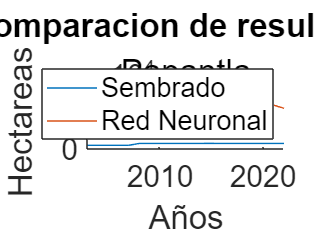

hold off


figure
hold on
plot(eage_x,data_result)

disp("error cuadratico medio")

error cuadratico medio


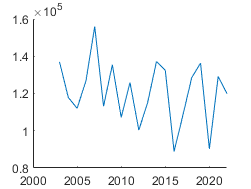

hold off

## Marcar zonas

indxs=find(info_hdf.anio==2022);
% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

datos=arr_ndvi_sgf(:,:,indxs);

data_tab_function=f_aplica_formulas(datos,study_area,1);
% data_tab_function=f_training_data(datos,study_area,1);

data_ndvi=data_tab_function(:,1:8);
% data_ndvi=data_tab_function(:,1);

class_result=model_entrenado.predictFcn(data_ndvi);

Error using array2table
The VariableNames property must contain one name for each variable in the table.

Error in mlearnapp.internal.model.DatasetSpecification>@(x)array2table(x,'VariableNames',predictorNames) (line 169)
                    predictorExtractionFcn = @(x) array2table(x, 'VariableNames',  predictorNames);

Error in 


area_naranja=f_make_area(datos,class_result,study_area);

area_clasificada=datos;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),archivo_kml,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 


% Perform k-means clustering using specified number of clusters (K value)
K = 3;
[clusterIndices,centroids] = kmeans(X,K);
clear K

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices,colormap("lines"));
for i2 = 1:numel(h)
    h(i2).DisplayName = strcat("Cluster",h(i2).DisplayName);
end
clear h i2 score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");